检查数据库中各Block在指定回合时段发生漏光的概率

确认漏光后可以使用LightLeakageInterpolation方法进行消除

## 语法

## 示例

将数据库中漏光概率最大的Block作成代表性线图。

## 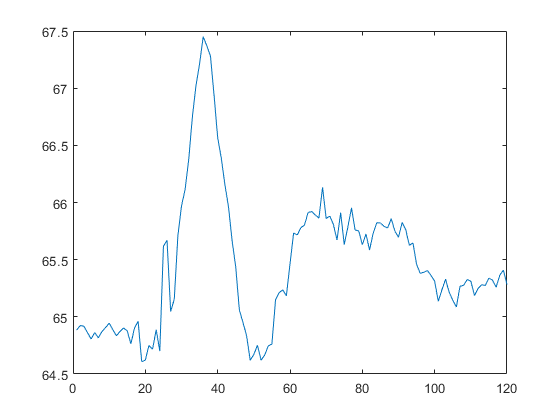

此数据库可见0~0.2s处的确出现一个疑似漏光的峰。检查LightLeakageProbabilities：

此函数使用二项分布检验判定前三个Block几乎100%有漏光，下面其余Block则概率较小。下面通常将确信漏光（一般取置信度0.95以上）的Block交给LightLeakageInterpolation方法进行插值修复。

## 输入参数

LightingPeriod(1,2)duration，给光的时间段，相对于回合的拆分定义点（而不是开始时间），详见TagSplitTrial文档

LightStimuli(1,:)categorical，有可能漏光的刺激类型。如不指定此参数，所有刺激类型都会被视为可能漏光的。除非所有刺激类型均可能漏光，否则一般应当指定此参数，特别是存在多种刺激类型穿插的Block中，如果某些刺激类型本身不可能漏光而不被排除，则可能拉低那些可能漏光的刺激类型的漏光概率

## 返回值

LightLeakageProbabilities(:,2)table，包含BlockUID和Probability两列，每行标识一个Block的漏光概率。通常可以认为概率>0.95即为显著性漏光。

**See also** [UniExp.DataSet.LightLeakageInterpolation](matlab:doc UniExp.DataSet.LightLeakageInterpolation) [UniExp.DataSet.TagSplitTrial](matlab:doc UniExp.DataSet.TagSplitTrial)

function LightLeakageProbabilities=CheckForLightLeakage(obj,LightingPeriod,LightStimuli)
arguments
	obj
	LightingPeriod(1,2)
	LightStimuli
end
if isMATLABReleaseOlderThan('R2024b')
	UniExp.Exception.Method_relies_on_2024b.Throw;
end
if nargin>2
	LightStimuli={'Stimulus',LightStimuli};
else
	LightStimuli={};
end
LightLeakageProbabilities=MATLAB.DataTypes.Select(["BlockUID","SeriesInterval","SampleRange"],{obj.DateTimes,obj.Blocks,obj.Trials},LightStimuli{:});
LightLeakageProbabilities.SampleRange=LightLeakageProbabilities.SampleRange.Tag-LightLeakageProbabilities.SampleRange.Start;
LightLeakageProbabilities=unique(LightLeakageProbabilities);
[Count,BlockUID]=groupcounts(LightLeakageProbabilities.BlockUID);
Logical=Count>1;
if any(Logical)
	UniExp.Exception.Blocks_of_different_Trial_splitting_methods.Throw(join(string(BlockUID(Logical)),' '));
end
LightingPeriod=int32(LightingPeriod./LightLeakageProbabilities.SeriesInterval)+LightLeakageProbabilities.SampleRange;
BlockTrialSignals=MATLAB.DataTypes.Select(["BlockUID","TrialSignal"],{obj.TrialSignals,obj.Trials},LightStimuli{:},BlockUID=LightLeakageProbabilities.BlockUID);
for B=1:height(LightLeakageProbabilities)
	MaxIndex=MATLAB.ElMat.PadCat(1,BlockTrialSignals.TrialSignal{BlockTrialSignals.BlockUID==LightLeakageProbabilities.BlockUID(B)},Padder=NaN);
	if isempty(MaxIndex)
		LightLeakageProbabilities.Probability(B)=NaN;
	else
		From=LightingPeriod(B,1);
		To=LightingPeriod(B,2);
		Duration=single(To-From);
		[~,MaxIndex]=max(MaxIndex(:,From-1:To+1),[],2,'omitmissing');
		MaxIndex(ismissing(MaxIndex))=[];
		LightLeakageProbabilities.Probability(B)=binocdf(sum(isbetween(MaxIndex,2,Duration+2)),height(MaxIndex),(Duration+1)/(Duration+3));
	end
end
LightLeakageProbabilities(ismissing(LightLeakageProbabilities.Probability),:)=[];
LightLeakageProbabilities=LightLeakageProbabilities(:,["BlockUID","Probability"]);
end